clc; close all;

load('meanHistRGB9_dobles.mat');
load('histogram_capilares.mat');

img_path = fullfile('fundus_images'); %Esto no va a ser encesario al meterlo en la aplicación
SinCaps_path = fullfile('Capilares','SinCaps_2605'); %Esto no va a ser encesario al meterlo en la aplicación

metadata_path = fullfile('Válidos2.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

%La muestras con validez=0 son las que se han podido segmentar
%correctamente y son las que se van a usar para entrenar el modelo.
T(T.Validez ~= 0, :) = [];
n=height(T);

%Se inicializan las variables
area=zeros(n,1);
entropia=zeros(n,1);
ratio=zeros(n,1);
media=zeros(n,1);
energia_cD=zeros(n,1);
media_cD=zeros(n,1);

% Con es
for k=1:n
k=k
RGB = imread(string(fullfile(img_path, T{k,1})));
[RGB, alto_original, ancho_original]=OD_Localization_Preprocessing(RGB);

R = RGB(:,:,1); 
Tr = graythresh(R);
IrT = imbinarize(R, Tr);
IrTE = edge(IrT, 'Sobel');
IrTE = imdilate(IrTE,strel('disk',30));

umbralBrightnessG=0.86;
[IgT_cleaned, cc2]=G_layer_BrightestRegion_HistogramTemplateMatching(RGB,umbralBrightnessG,meanHistRGB,IrTE);
if cc2.NumObjects==0
umbralBrightnessG=0.60;
[IgT_cleaned,~]=G_layer_BrightestRegion_HistogramTemplateMatching(RGB,umbralBrightnessG,meanHistRGB,IrTE);
end
I=rgb2gray(RGB);
brightest_region = imoverlay(I,IgT_cleaned,'blue');
[SinCaps,mascaraCapilares]=extraerCapilaresDeFundus(RGB, histogram_capilares);
modo=3;
[ROI,ROI_SinCaps, ~, centroides_originales]=extraerROI(IgT_cleaned,modo,RGB,SinCaps);

[OD, maskOD, bordesOD, Validez]=ODsegmentation(ROI_SinCaps, []);
[area(k), entropia(k), ratio(k), media(k), energia_cD(k), media_cD(k)]=featuresfinal(OD, ROI, maskOD, ancho_original);
end

k = 1

imagen=T.image;
glaucoma=T.glaucoma;

tabla = table(imagen, glaucoma, area, entropia, ratio, media, energia_cD, media_cD, ...
    'VariableNames', {'Imagen','Glaucoma','Area', 'Entropia', 'Ratio', 'Media', 'Energia_cD', 'Media_cD'});

% Mostrar la tabla combinada
disp(tabla)

% Establecer la semilla del generador de números aleatorios para reproducibilidad
rng(0); % Puedes cambiar '0' por cualquier otro número para cambiar la semilla


figure;
histogram(categorical(tabla.Glaucoma));

% Contar la cantidad de 0s y 1s en la variable glaucoma
num_ceros = sum(tabla.Glaucoma == 0);
num_unos = sum(tabla.Glaucoma == 1);

% Calcular la diferencia y determinar cuántas filas eliminar
num_eliminar = abs(num_ceros - num_unos);

if num_ceros > num_unos
    % Hay más ceros, eliminar filas con ceros
    indices_ceros = find(tabla.Glaucoma == 0);
    indices_eliminar = randsample(indices_ceros, num_eliminar);
else
    % Hay más unos, eliminar filas con unos
    indices_unos = find(tabla.Glaucoma == 1);
    indices_eliminar = randsample(indices_unos, num_eliminar);
end

% Eliminar las filas seleccionadas
tabla_proporcionada = tabla;
tabla_proporcionada(indices_eliminar, :) = [];

% Mostrar la nueva tabla proporcionada
disp(tabla_proporcionada);

figure;
histogram(categorical(tabla_proporcionada.Glaucoma));

% Guardar la tabla combinada en el archivo 'variables.mat'
writetable(tabla_proporcionada, 'tabla_proporcionada.csv');

Dale a run desde aquí para no tener que esperar a que cargue el for

tabla_proporcionada=readtable(fullfile('tabla_proporcionada.csv'));
tabla_de_variables = removevars(tabla_proporcionada, {'Imagen', 'Glaucoma'});

Se lleva a cabo un análisis Chi-Square

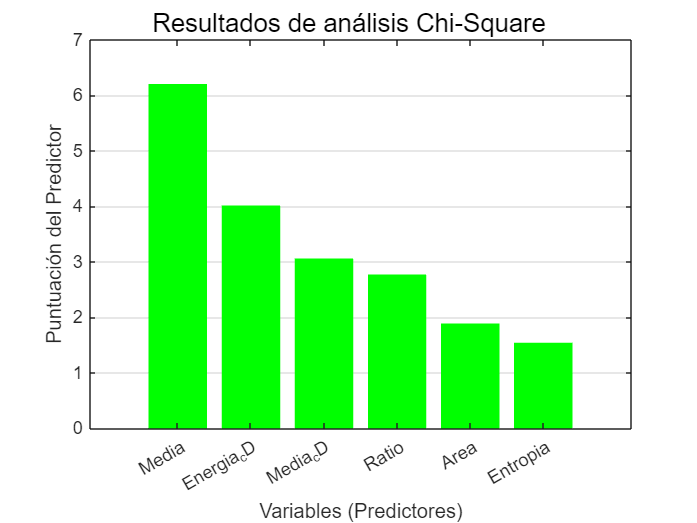

[idx, scores] = fscchi2(tabla_de_variables, tabla_proporcionada.Glaucoma);
figure;
sgtitle('Resultados de análisis Chi-Square')
b = bar(scores(idx), 'FaceColor', 'flat'); % Crea las barras con colores planos


b.CData = [0 1 0]; % Color verde
b.EdgeColor = 'none'; % Bordes transparentes

set(gca, 'XTick', 1:length(idx), 'XTickLabel', tabla_de_variables.Properties.VariableNames(idx))
xlabel('Variables (Predictores)')
ylabel('Puntuación del Predictor')
set(gca, 'XGrid', 'off', 'YGrid', 'on') % Activa la cuadrícula solo en el eje X

Se comprueba la correlación entre las variables seleccionadas

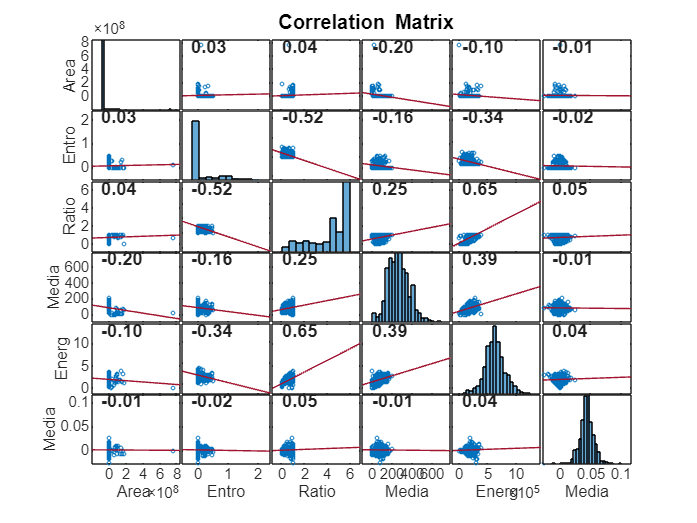

figure;
corrplot(tabla_de_variables);

Se proporciona la tabla para evitar class-imbalance

rng(0);
% Obtener el número de filas para la tabla de entrenamiento y test
num_filas = size(tabla_proporcionada, 1);
num_filas_entrenamiento = round(0.8 * num_filas);
num_filas_test = num_filas - num_filas_entrenamiento;

% Obtener índices aleatorios para las filas de entrenamiento y test
indices_entrenamiento = datasample(1:num_filas, num_filas_entrenamiento, 'Replace', false);
indices_test = setdiff(1:num_filas, indices_entrenamiento);

% Crear las tablas de entrenamiento y test
tabla_entrenamiento = tabla_proporcionada(indices_entrenamiento, :);
tabla_test = tabla_proporcionada(indices_test, :);

Se entrenan y evaluan tres modelos (SVN, Kernel y Tree).

[modelo_SVN, validationAccuracy_SVN] = trainClassifier(tabla_entrenamiento);
[ytested_SVN,scores_SVN] = modelo_SVN.predictFcn(tabla_test);
probabilidades = 1 ./ (1 + exp(-scores_SVN));

% Calcular la precisión del test
testAccuracy_SVN = sum(ytested_SVN == tabla_test.Glaucoma) / numel(tabla_test.Glaucoma);
disp(['Test Accuracy: ' num2str(testAccuracy_SVN)]);

Test Accuracy: 0.65455


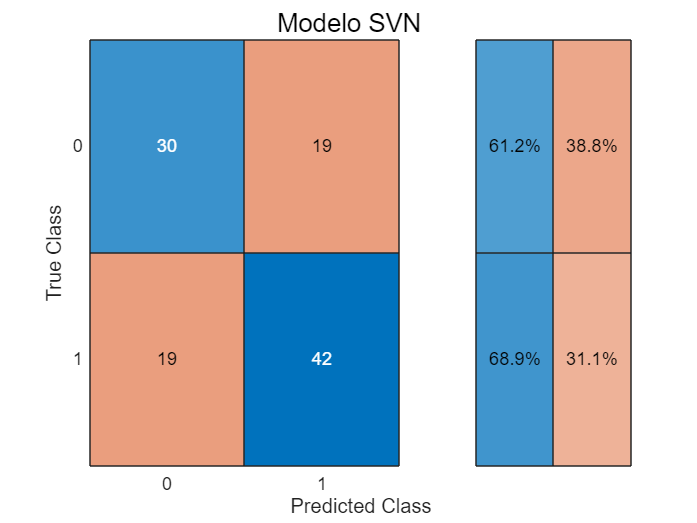


figure;
sgtitle('Modelo SVN');
cm = confusionchart(ytested_SVN,tabla_test.Glaucoma,'RowSummary', 'row-normalized');

[modelo_Kernel, validationAccuracy_Kernel] = trainClassifier2(tabla_entrenamiento);
[ytested_Kernel,scores_Kernel] = modelo_Kernel.predictFcn(tabla_test);
probabilidades_Kernel = 1 ./ (1 + exp(-scores_Kernel));

% Calcular la precisión del test
testAccuracy_Kernel = sum(ytested_Kernel == tabla_test.Glaucoma) / numel(tabla_test.Glaucoma);
disp(['Test Accuracy: ' num2str(testAccuracy_Kernel)]);

Test Accuracy: 0.47273


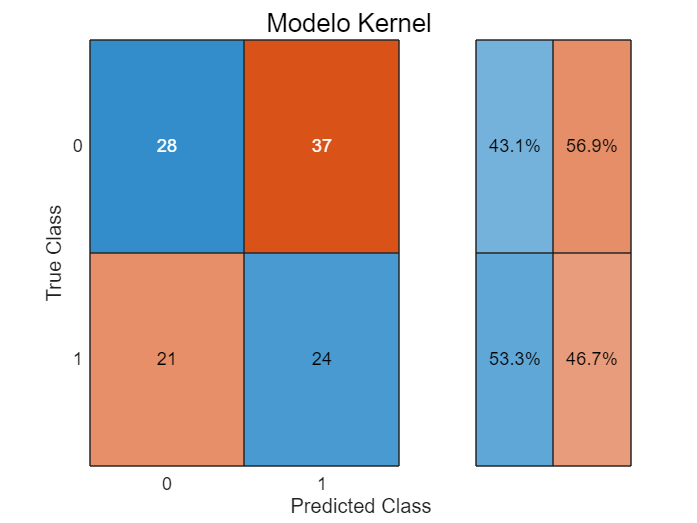

figure;
sgtitle('Modelo Kernel');
cm = confusionchart(ytested_Kernel,tabla_test.Glaucoma,'RowSummary', 'row-normalized');

[modelo_Tree, validationAccuracy_Tree] = trainClassifier3(tabla_entrenamiento);
[ytested_Tree,scores_Tree] = modelo_Tree.predictFcn(tabla_test);
probabilidades_Tree = 1 ./ (1 + exp(-scores_Tree));
% Calcular la precisión del test
testAccuracy_Tree = sum(ytested_Tree == tabla_test.Glaucoma) / numel(tabla_test.Glaucoma);

disp(['Test Accuracy: ' num2str(testAccuracy_Tree)]);

Test Accuracy: 0.65455


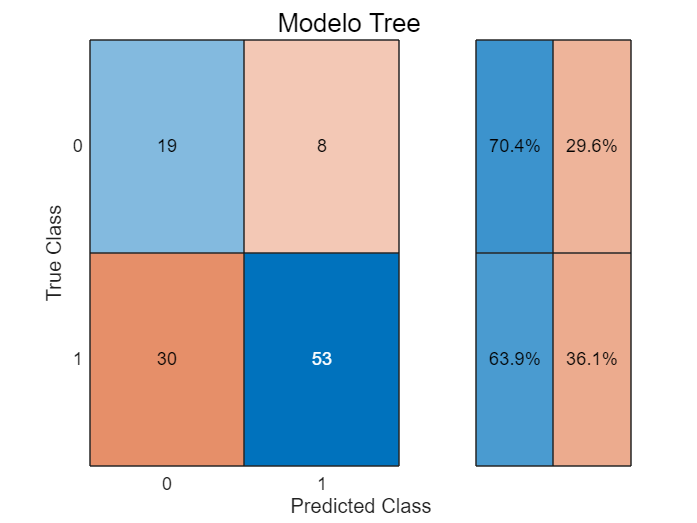


figure;
sgtitle('Modelo Tree');
cm = confusionchart(ytested_Tree,tabla_test.Glaucoma,'RowSummary', 'row-normalized');

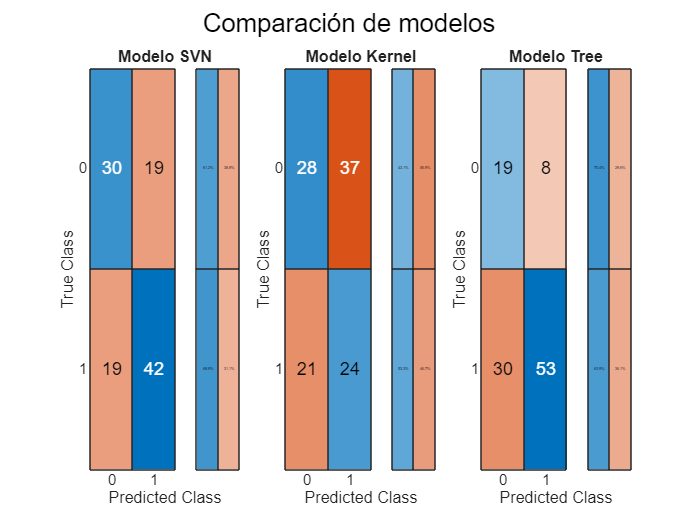

figure;
sgtitle('Comparación de modelos');
subplot(1,3,1);
cm = confusionchart(ytested_SVN,tabla_test.Glaucoma,'RowSummary', 'row-normalized');
title('Modelo SVN');
subplot(1,3,2);
cm = confusionchart(ytested_Kernel,tabla_test.Glaucoma,'RowSummary', 'row-normalized');
title('Modelo Kernel');
subplot(1,3,3);
cm = confusionchart(ytested_Tree,tabla_test.Glaucoma,'RowSummary', 'row-normalized');
title('Modelo Tree');

Finalemente se selecciona el primer modelos (SVN) ya que ofrece la mayor cantidad de positivos reales (68.9%).

save('modelo_SVN.mat', 'modelo_SVN');